clc;
clear;
close all;

% Punto 1
imge = load('RealToulouse.mat');
whos imge

  Name      Size               Bytes  Class     Attributes

  imge      1x1             61202600  struct              



I = imge.Real_after;
whos I

  Name        Size                   Bytes  Class     Attributes

  I         482x512x31            61202432  double              



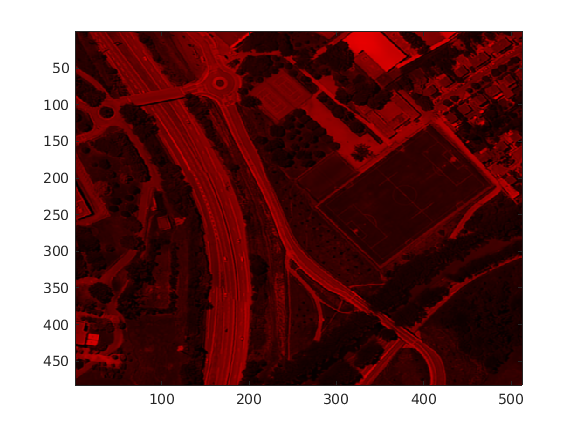


I_R = I(:,:,1);
I_G = I(:,:,16);
I_B = I(:,:,30);

zero = zeros(size(I, 1), size(I, 2));
redI = cat(3, I_R, zero, zero);
greenI = cat(3, zero, I_G, zero);
blueI = cat(3, zero, zero, I_B);
T = cat(3, I_R, I_G, I_B);

N=255;
s1= 0:1/(N-1):1;
mapR=zeros(N,3);
mapR(:,1,:)=s1;
mapG=zeros(N,3);
mapG(:,2,:)=s1;
mapB=zeros(N,3);
mapB(:,3,:)=s1;

figure
imagesc(I_R)
colormap(mapR)

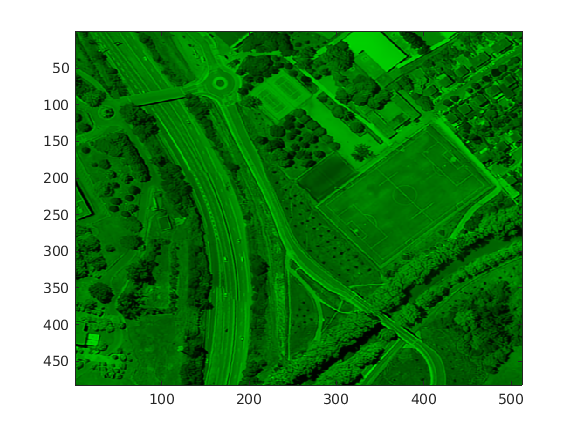

figure 
imagesc(I_G)
colormap(mapG)

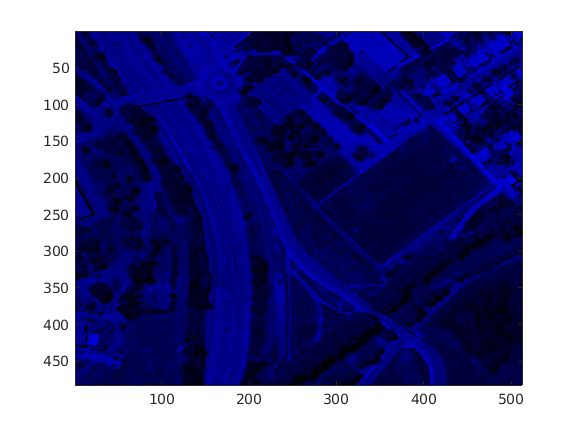

figure
imagesc(I_B)
colormap(mapB)

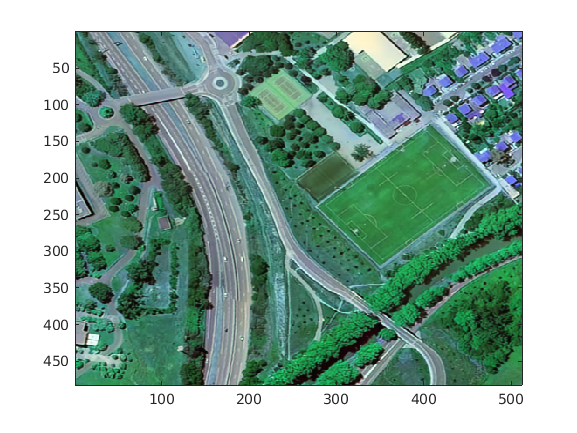

figure
imagesc(T)